# **Exact Potential Game**

Here we are using Potential Game and compare it to two-strategy game in the multi-cell scenario.

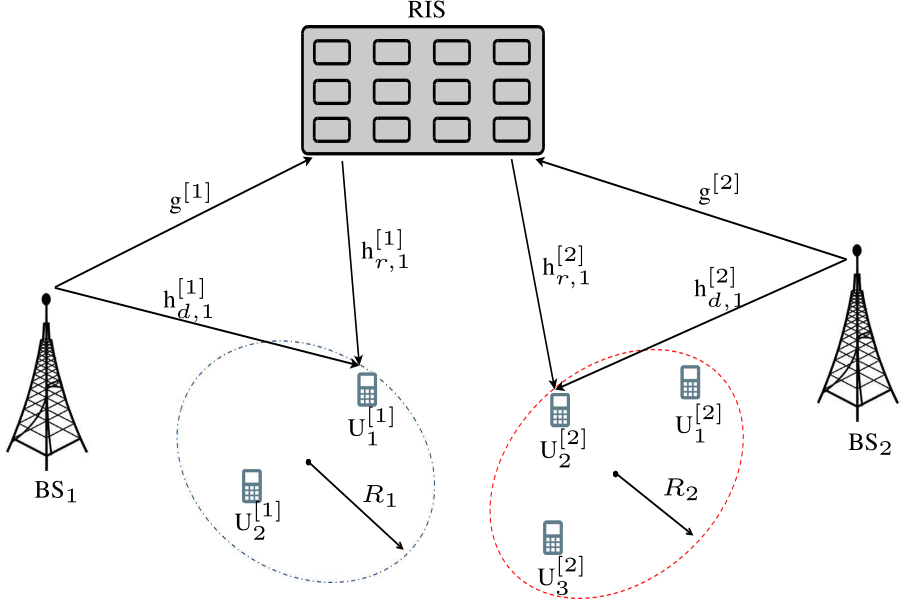

clc
close all
addpath('C:\Users\Asus irG\Documents\GitHub\RIS-Sharing-Scenario\modules\') % You need to change the address in case you run it on your computer

% Parameters
N1 = 4;                     % Number of users for BS1
N2 = 4;                     % Number of users for BS2
R1 = 10;                    % Radius of BS1 user area center
R2 = 10;                    % Radius of BS2 user area center    
N_i = 24;                   % Number of IRS elements
q_t = 1/8;                  % Quantization step-size
N_iter = 1;                 % Number of iterations for simulation
SV = 5;                     % Scenario Variable
P_T = (10^(40/10)) * 1e-3;  % BS power (in watts)
% [x0, y0, z0] = deal(50, 20, 0);            % User area center
[x1, y1, z1] = deal(0, 0, 0);               % BS1 location
[x2, y2, z2] = deal(100, 10, 0);            % BS2 location
[x_i, y_i, z_i] = deal(50, 30, 10);         % IRS location
M_t = 1;                    % Number of transmitter antennas
M_r = 1;                    % Number of receiver antennas
d_IB = 100;                 % Distance between IRS and BSs
alpha_d = 3.76;             % Path loss exponent parameter for distance
alpha_r = 2;                % Path loss exponent parameter for height
BW = 10e7;                  % System bandwidth (in Hz)
noise_power = (10^(-114/10));               % Noise power (in watts, -169dBm/Hz)
r = 0.3;                    % Fraction of IRS interference to be removed
interference = 0;           % Interference between two BSs (0 for no interference)
epsilon = 0.05;             % Error tolerance parameter
seedValue = 1;              % Seed for generating channel response 
discrete = false;           % Discrete mode for optimization
N_bits = 3;



%% Users location
x = zeros(N1 + N2, 1);
y = zeros(N1 + N2, 1);
z = 1.5 * ones(N1 + N2, 1);
x(1:N1) = 35;
x(N1 + 1:N2 + N1) = 55;
y(1:N1) = 25;
y(N1 + 1:N2 + N1) = 10;

## Utility vs Distance

%% Calculating Rates
rate = zeros(ceil(1/q_t) + 1, ceil(1/q_t) + 1, 2, SV);
EPG_utility = zeros(ceil(1/q_t) + 1, ceil(1/q_t) + 1, 2, SV);
TSG_utility = zeros(2, 2, 2, SV);
P = zeros(2, SV, 1);
NE_final_utility = zeros(2, SV);
s1_star = zeros(SV, 1);
s2_star = zeros(SV, 1);
EPG_final_utility = zeros(2, SV);
step = 5;
start = 8;
m = repmat('.', 1, SV);
tic

for d = start + 0 * step:step:start + (SV - 1) * step
    m(1 + floor((d - start) / step)) = '|';
    disp(m)
    y(1:N1) = d;
    i = 1 + floor((d - start) / step);
    for j = 1:N_iter
        [~, rate(:, :, :, i)] = PotentialGame(M_t, M_r, N1, N2, N_i, P_T, x, y, z, x1, y1, z1, ...
            x2, y2, z2, x_i, y_i, z_i, alpha_d, alpha_r, noise_power, 1, ...
            [R1; R2], r, q_t, interference, epsilon);
        TSG_utility(1, 1, 1, i) = N1 * rate(1, 1, 1, i);
        TSG_utility(1, 1, 2, i) = N2 * rate(1, 1, 2, i);
        TSG_utility(1, 2, 1, i) = N1 * rate(1, end, 1, i);
        TSG_utility(2, 1, 2, i) = N2 * rate(end, 1, 2, i);
        
        TSG_utility(1, 2, 2, i) = N2 * rate(1, end, 2, i) - r * N_i;
        TSG_utility(2, 1, 1, i) = N1 * rate(end, 1, 1, i) - r * N_i;
        
        TSG_utility(2, 2, 1, i) = N1 * rate(1 + floor(size(rate, 1) / 2), 1 + floor(size(rate, 2) / 2), 1, i) - r * N_i / 2;
        TSG_utility(2, 2, 2, i) = N2 * rate(1 + floor(size(rate, 1) / 2), 1 + floor(size(rate, 2) / 2), 2, i) - r * N_i / 2;
        
        P(:, i) = NE(TSG_utility(:, :, :, i));
        NE_final_utility(:, i) = NE_final_utility(:, i) + P(1, i) * P(2, i) * [TSG_utility(1, 1, 1, i); TSG_utility(1, 1, 2, i)] + ...
            P(1, i) * (1 - P(2, i)) * [TSG_utility(1, 2, 1, i); TSG_utility(1, 2, 2, i)] + ...
            (1 - P(1, i)) * P(2, i) * [TSG_utility(2, 1, 1, i); TSG_utility(2, 1, 2, i)] + ...
            (1 - P(1, i)) * (1 - P(2, i)) * [TSG_utility(2, 2, 1, i); TSG_utility(2, 2, 2, i)];
        for s1 = 1:ceil(1/q_t) + 1
            for s2 = 1:ceil(1/q_t) + 1
                N_i1 = floor((s1 - 1) * N_i * q_t); % No. of elements allocated to BS1
                N_i2 = floor((s2 - 1) * N_i * q_t); % No. of elements allocated to BS2
                EPG_utility(s1, s2, 1, i) = N1 * rate(s1, s2, 1, i) - N_i1 * r;
                EPG_utility(s1, s2, 2, i) = N2 * rate(s1, s2, 2, i) - N_i2 * r;
            end
        end
        F = sum(EPG_utility(:, :, :, i), 3);
        maximum = max(max(F));
        [s1_star(i), s2_star(i)] = find(F == maximum);
        temp = EPG_utility(s1_star(i), s2_star(i), :, i);
        EPG_final_utility(:, i) = EPG_final_utility(:, i) + temp(:);
    end
end

|....
||...
|||..
||||.
|||||


NE_final_utility = NE_final_utility / N_iter;
EPG_final_utility = EPG_final_utility / N_iter;
 

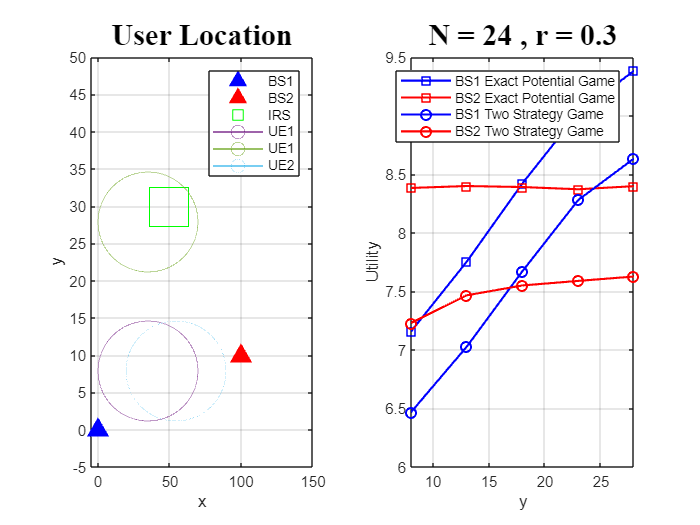

%% Plot Utility
figure
tiledlayout(1, 2)

% Plot User Location
nexttile
% Draw BS1
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11, 'LineWidth', 1.5);
plot(0, 0, '^', 'MarkerSize', 10, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b', 'linewidth', 1)
hold on
% Draw BS2
plot(x2, y2, '^', 'MarkerSize', 10, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r', 'linewidth', 1)
% Draw IRS
plot(x_i, y_i, 'gs', 'MarkerSize', 30, 'linewidth', 1)
% Draw BS1 users
plot(x(1), start, 'o-', 'MarkerSize', 60 * R1 / 10, 'linewidth', 0.3)
plot(x(1), d, 'o-', 'MarkerSize', 60 * R1 / 10, 'linewidth', 0.3)
% Draw BS2 users
plot(x(N1 + 1), start, 'o-', 'MarkerSize', 60 * R1 / 10, 'linewidth', 0.1)
% Configurations
title('User Location', 'FontName', 'Times New Roman', 'FontSize', 18)
xlabel('x')
ylabel('y')
xlim([-5 150])
ylim([-5 50])
legend('BS1', 'BS2', 'IRS', 'UE1', 'UE1', 'UE2')
grid on

% Plot Results
nexttile
% Draw EPG final utility for BS1
plot(start:step:(SV - 1) * step + start, EPG_final_utility(1, 1:SV), 'b-s', 'linewidth', 1.25)
hold on
% Draw EPG final utility for BS2
plot(start:step:(SV - 1) * step + start, EPG_final_utility(2, 1:SV), 'r-s', 'linewidth', 1.25)
% Draw NE final utility for BS1
plot(start:step:(SV - 1) * step + start, NE_final_utility(1, 1:SV), 'b-o', 'linewidth', 1.25)
% Draw NE final utility for BS2
plot(start:step:(SV - 1) * step + start, NE_final_utility(2, 1:SV), 'r-o', 'linewidth', 1.25)
% Legend and configurations
legend('BS1 Exact Potential Game', 'BS2 Exact Potential Game', 'BS1 Two Strategy Game', 'BS2 Two Strategy Game')
grid on
set(gcf, 'color', 'w'); % Set the figure background to white
title(['N = ', num2str(N_i), ' , r = ', num2str(r)], 'FontName', 'Times New Roman', 'FontSize', 18)
xlabel('y')
ylabel('Utility')
xlim([start max((SV - 1) * step + start, start + step)])

## Utility vs No. tiles

%% Calculating Rates

% Define variables
step = 1;
start = 1;
SV = 10; % Assuming you have defined SV elsewhere
rate = zeros(1/(1/2^(start + (SV-1) * step-1))+1, 1/(1/2^(start + (SV-1) * step-1))+1, 2, SV);
m = repmat('.', 1, SV); % Initialize progress indicator
tic

% Loop for different values of N_t
for N_t = start + 0 * step : step : start + (SV-1) * step
    q_t = 1/2^(N_t - 1); % Calculate quantization step size
    i = N_t;
    m(i) = '|'; % Update progress indicator
    disp(m)
    pause(1) % Pause to visualize progress
    
    % Call PotentialGame function to calculate rates
    [~, rate(1:ceil(1/q_t)+1, 1:ceil(1/q_t)+1, :, i)] = PotentialGame(M_t, M_r, N1, N2, N_i, P_T, x, y, z, x1, y1, z1,...
                                        x2, y2, z2, x_i, y_i, z_i, alpha_d, alpha_r, noise_power, N_iter,...
                                        [R1; R2], r, q_t, interference, epsilon);
end

toc % Display elapsed time


|..
||.
|||


toc

Elapsed time is 3.030959 seconds.


%% NE in EPG and 2 strategy game

% Initialize variables
EPG_utility = zeros(1/(1/2^(start + (SV-1) * step-1))+1, 1/(1/2^(start + (SV-1) * step-1))+1, 2, SV);
s1_star = zeros(SV, 1);
s2_star = zeros(SV, 1);
EPG_final_rate = zeros(2, SV);
EPG_final_utility = zeros(2, SV);

% Loop over each value of SV
for i = 1:SV
    q_t = 1/2^(i - 1); % Calculate quantization step size
    
    % Loop over possible values of s1 and s2
    for s1 = 1:ceil(1/q_t)+1
        for s2 = 1:ceil(1/q_t)+1
            N_i1 = floor((s1-1) * N_i * q_t); % No. of elements allocated to BS1
            N_i2 = floor((s2-1) * N_i * q_t); % No. of elements allocated to BS2
            EPG_utility(s1, s2, 1, i) = N1 * rate(s1, s2, 1, i) - N_i1 * r; % Calculate utility for BS1
            EPG_utility(s1, s2, 2, i) = N2 * rate(s1, s2, 2, i) - N_i2 * r; % Calculate utility for BS2
        end
    end
    
    % Find s1_star and s2_star that maximize utility
    F = sum(EPG_utility(:, :, :, i), 3);
    maximum = max(max(F));
    [s1_star(i), s2_star(i)] = find(F == maximum);
    
    % Assign final rate and utility
    EPG_final_rate(:, i) = rate(s1_star(i), s2_star(i), :, i);
    EPG_final_utility(:, i) = EPG_utility(s1_star(i), s2_star(i), :, i);
end


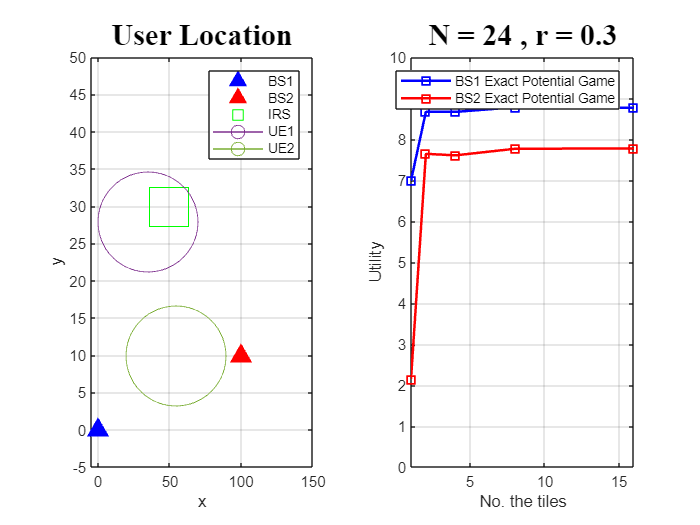

%% Plot Utility
figure

% Draw results
hvector = 2.^(start - 1 : step : (SV-1) * step + start - 1); % Create a vector for x-axis ticks
plot(hvector, EPG_final_utility(1, 1:SV), 'b-s', 'linewidth', 1.5) % Plot utility for BS1
hold on
plot(hvector, EPG_final_utility(2, 1:SV), 'r-s', 'linewidth', 1.5) % Plot utility for BS2

% Configure legend
legend('BS1 Exact Potential Game', 'BS2 Exact Potential Game'); 

% Configure plot
grid on
set(gcf, 'color', 'w'); % Set the figure background to white
title(['N = ', num2str(N_i), ' , r = ', num2str(r)], 'FontName', 'Times New Roman', 'FontSize', 18)
xlabel('No. the tiles')
ylabel('Utility')
xlim([start hvector(end)]); % Set x-axis limits 

## Central Optimization - utility vs power

the central optimization problem for finding power allocation and RIS configuration can be written as follows.

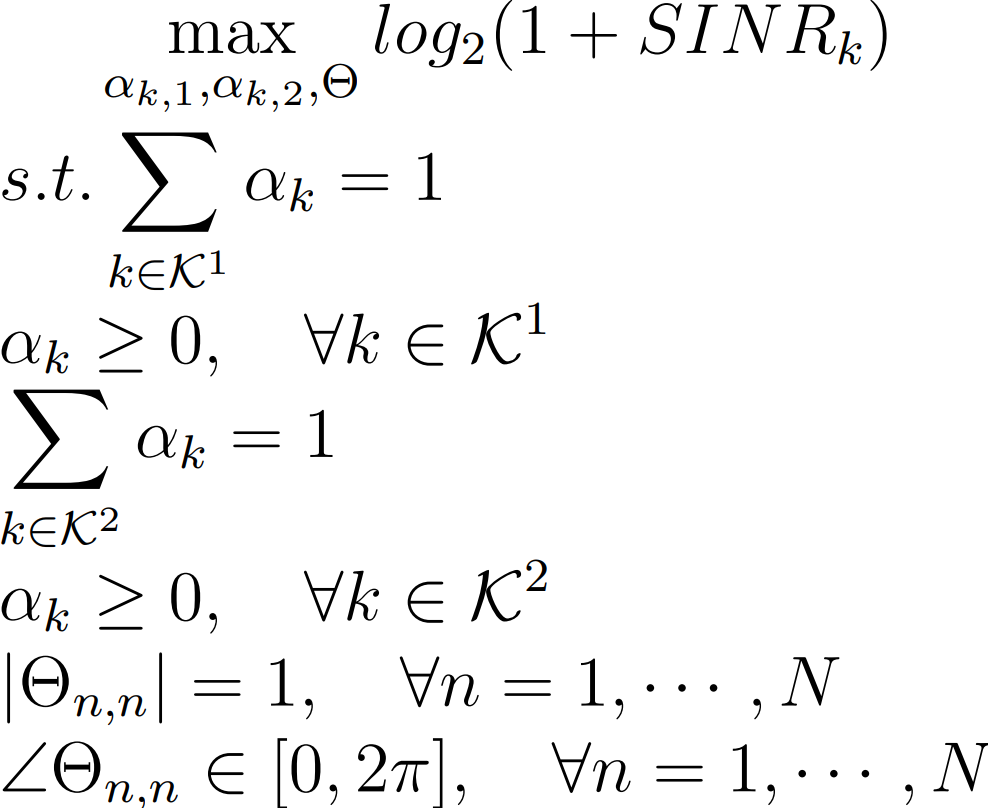

RIS cost will be equally divided between the BSs.

R1 = 15; % Set R1
R2 = 15; % Set R2

%% Calculating Rates
rate = zeros(ceil(1/q_t)+1, ceil(1/q_t)+1, 2, SV);
EPG_utility = zeros(ceil(1/q_t)+1, ceil(1/q_t)+1, 2, SV);
TSG_utility = zeros(2, 2, 2, SV);
P = zeros(2, SV, 1);
NE_final_rate = zeros(2, SV);
NE_final_utility = zeros(2, SV);
s1_star = zeros(SV, 1);
s2_star = zeros(SV, 1);
EPG_final_rate = zeros(2, SV);
EPG_final_utility = zeros(2, SV);
central_opt_rate = zeros(2, SV);
central_opt_utility = zeros(2, SV);
step = 5;
start = 10;
m = repmat('.', 1, SV);
tic

for P_T = start + 0 * step : step : start + (SV-1) * step
    m(1 + floor((P_T-start)/step)) = '|';
    clc
    disp(m)
    i = 1 + floor((P_T-start)/step);
    P_T = (10^(P_T/10)) * 1e-3; % Calculate P_T based on current step
    for j = 1:N_iter
        % Two Strategy Game
        [~, rate(:, :, :, i)] = PotentialGame(M_t, M_r, N1, N2, N_i, P_T, x, y, z, x1, y1, z1,...
            x2, y2, z2, x_i, y_i, z_i, alpha_d, alpha_r, noise_power, 1,...
            [R1; R2], r, q_t, interference, epsilon);
        % Exact Potential Game
        for s1 = 1:ceil(1/q_t)+1
            for s2 = 1:ceil(1/q_t)+1
                N_i1 = floor((s1-1) * N_i * q_t); % No. of elements allocated to BS1
                N_i2 = floor((s2-1) * N_i * q_t); % No. of elements allocated to BS2
                EPG_utility(s1, s2, 1, i) = N1 * rate(s1, s2, 1, i) - N_i1 * r;
                EPG_utility(s1, s2, 2, i) = N2 * rate(s1, s2, 2, i) - N_i2 * r;
            end
        end
        F = sum(EPG_utility(:, :, :, i), 3);
        maximum = max(max(F));
        [s1_star(i), s2_star(i)] = find(F == maximum);
        temp = EPG_utility(s1_star(i), s2_star(i), :, i);
        EPG_final_utility(:, i) = EPG_final_utility(:, i) + temp(:);

        % Central Optimization
        [central_opt_rate(:, i), ~] = central_opt(M_t, M_r, N1, N2, N_i, P_T, x, y, z, x1, y1, z1,...
            x2, y2, z2, x_i, y_i, z_i, alpha_d, alpha_r, noise_power, 1,...
            [R1; R2], discrete, interference, epsilon);
        central_opt_utility(1, i) = central_opt_utility(1, i) + N1 * central_opt_rate(1, i) - r * N_i/2;
        central_opt_utility(2, i) = central_opt_utility(2, i) + N2 * central_opt_rate(2, i) - r * N_i/2;
    end
end
toc
NE_final_rate = NE_final_rate / N_iter;
NE_final_utility = NE_final_utility / N_iter;
EPG_final_rate = EPG_final_rate / N_iter;
EPG_final_utility = EPG_final_utility / N_iter;
central_opt_utility = central_opt_utility / N_iter;


%% Plot Utility
figure

% Draw results for Central Optimization
plot(start : step : (SV-1) * step+start , central_opt_utility(1 , 1 : SV) , 'b--o' , 'linewidth' , 1.5)
hold on
plot(start : step : (SV-1) * step+start , central_opt_utility(2 , 1 : SV) , 'r--o' , 'linewidth' , 1.5)

% Draw results for Exact Potential Game
plot(start : step : (SV-1) * step+start , EPG_final_utility(1 , 1 : SV) , 'b-s' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start , EPG_final_utility(2 , 1 : SV) , 'r-s' ,  'linewidth' , 1.5)

% Draw results for NE in Two Strategy Game
plot(start : step : (SV-1) * step+start , NE_final_utility(1 , 1 : SV) , 'b-o' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start , NE_final_utility(2 , 1 : SV) , 'r-o' , 'linewidth' , 1.5)

% Legend
lgnd = legend('BS1 Central Optimization' , 'BS2 Central Optimization' ,'BS1 Exact Potential Game' , 'BS2 Exact Potential Game' , 'BS1 Two Strategy Game' ,  'BS2 Two Strategy Game') ;
set(lgnd,'FontSize',18);
set(lgnd,'FontName','Times New Roman');

grid on
set(gcf , 'color' , 'w');   % Set the figure background to white

% Axes labels and limits
xlabel('Transmit Power (dBm)' , 'FontName','Times New Roman', 'FontSize',18 , 'FontWeight', 'bold' )
ylabel('Utility' , 'FontName','Times New Roman', 'FontSize',18 , 'FontWeight', 'bold')
xlim([start max((SV-1) * step+start , start+step)]) ; 
